Akima Interpolation

P=[0 0 ; 1 2; 3 1; 4 3; 5 3; 6 0]

P =      0     0
     1     2
     3     1
     4     3
     5     3
     6     0


P=[0.000000, 0.000000, 0.100000, 1.000000;
0.306796, 0.383495, 0.20000, 1.000000;
0.383495, 0.766990, 0.500000, 1.000000;
0.414175, 1.227185, 0.500000, 1.000000;
0.429515, 1.441942, 0.500000, 1.000000;
0.613592, 1.687379, 0.500000, 1.000000;
1.073787, 1.963495, 0.500000, 1.000000;
1.533981, 2.235010, 0.500000, 1.000000;
1.687379, 1.840777, 0.500000, 1.000000;
1.687379, 1.478757, 0.500000, 1.000000;
1.687379, 2.454369, 0.500000, 1.000000;
1.687379, 2.607767, 0.500000, 1.000000]

P =          0         0    0.1000    1.0000
    0.3068    0.3835    0.2000    1.0000
    0.3835    0.7670    0.5000    1.0000
    0.4142    1.2272    0.5000    1.0000
    0.4295    1.4419    0.5000    1.0000
    0.6136    1.6874    0.5000    1.0000
    1.0738    1.9635    0.5000    1.0000
    1.5340    2.2350    0.5000    1.0000
    1.6874    1.8408    0.5000    1.0000
    1.6874    1.4788    0.5000    1.0000



plot(P(:,1),P(:,2))
hold on
grid on
plot(P(:,1),P(:,2),'r*')

num= length(P)

num = 12

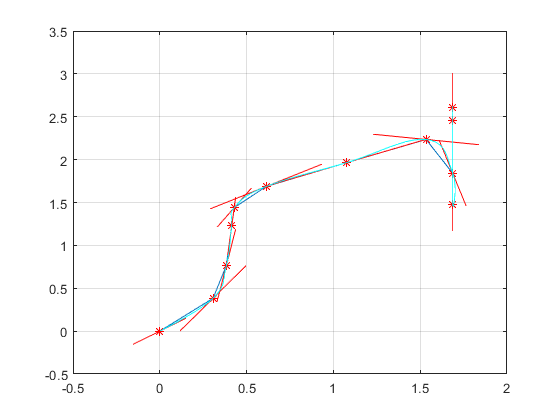

lt=0.5;
Tg= zeros(num,4);
% tangenten
Tg(1,:)= P(2,1)-P(1,2);
p1= P(1,:)-Tg(1,:)*lt;
p2= P(1,:)+Tg(1,:)*lt;
plot([p1(1),p2(1)],[p1(2),p2(2)],'r')

for n=2: num-1
Tg(n,:)= P(n+1,:)-P(n-1,:);
p1= P(n,:)-Tg(n,:)*lt;
p2= P(n,:)+Tg(n,:)*lt;
plot([p1(1),p2(1)],[p1(2),p2(2)],'r')
end

Tg(num,:)=  (P(num,:)-P(num-1,:));
p1= P(num,:)-Tg(num,:)*lt;
p2= P(num,:)+Tg(num,:)*lt;
plot([p1(1),p2(1)],[p1(2),p2(2)],'r')


A= [1 1 1 1;
    0 0 0 1;
    3 2 1 0;
    0 0 1 0];
Tg= Tg*0.6;
Tg(1,:)=Tg(1,:)*0.0;
Tg(num,:)=Tg(num,:)*0.0;
l=0:0.1:1;

for n=2:num
b1= [P(n,1), P(n-1,1), Tg(n,1), Tg(n-1,1)]';
b2= [P(n,2), P(n-1,2), Tg(n,2), Tg(n-1,2)]';

p1= A\b1;
p2= A\b2;

plot(polyval(p1,l),polyval(p2,l),'c')
end
hold off

Symbolysche Lösung


As3 = sym('As3',[4 4])

$$As3 = \left(\begin{array}{cccc} {\mathrm{As}}_{31,1} & {\mathrm{As}}_{31,2} & {\mathrm{As}}_{31,3} & {\mathrm{As}}_{31,4}\\ {\mathrm{As}}_{32,1} & {\mathrm{As}}_{32,2} & {\mathrm{As}}_{32,3} & {\mathrm{As}}_{32,4}\\ {\mathrm{As}}_{33,1} & {\mathrm{As}}_{33,2} & {\mathrm{As}}_{33,3} & {\mathrm{As}}_{33,4}\\ {\mathrm{As}}_{34,1} & {\mathrm{As}}_{34,2} & {\mathrm{As}}_{34,3} & {\mathrm{As}}_{34,4} \end{array}\right)$$

As3= [1 1 1 1;
    0 0 0 1;
    3 2 1 0;
    0 0 1 0];
b3 = sym('b3',[4 1])

$$b3 = \left(\begin{array}{c} b_{31}\\ b_{32}\\ b_{33}\\ b_{34} \end{array}\right)$$

cs3= As3\b3

$$cs3 = \left(\begin{array}{c} 2\,b_{32}-2\,b_{31}+b_{33}+b_{34}\\ 3\,b_{31}-3\,b_{32}-b_{33}-2\,b_{34}\\ b_{34}\\ b_{32} \end{array}\right)$$

 b3=[1 1 1 1 ];

polyder(b3)

ans =      3     2     1


As5 = sym('As5',[6 6])

$$As5 = \left(\begin{array}{cccccc} {\mathrm{As}}_{51,1} & {\mathrm{As}}_{51,2} & {\mathrm{As}}_{51,3} & {\mathrm{As}}_{51,4} & {\mathrm{As}}_{51,5} & {\mathrm{As}}_{51,6}\\ {\mathrm{As}}_{52,1} & {\mathrm{As}}_{52,2} & {\mathrm{As}}_{52,3} & {\mathrm{As}}_{52,4} & {\mathrm{As}}_{52,5} & {\mathrm{As}}_{52,6}\\ {\mathrm{As}}_{53,1} & {\mathrm{As}}_{53,2} & {\mathrm{As}}_{53,3} & {\mathrm{As}}_{53,4} & {\mathrm{As}}_{53,5} & {\mathrm{As}}_{53,6}\\ {\mathrm{As}}_{54,1} & {\mathrm{As}}_{54,2} & {\mathrm{As}}_{54,3} & {\mathrm{As}}_{54,4} & {\mathrm{As}}_{54,5} & {\mathrm{As}}_{54,6}\\ {\mathrm{As}}_{55,1} & {\mathrm{As}}_{55,2} & {\mathrm{As}}_{55,3} & {\mathrm{As}}_{55,4} & {\mathrm{As}}_{55,5} & {\mathrm{As}}_{55,6}\\ {\mathrm{As}}_{56,1} & {\mathrm{As}}_{56,2} & {\mathrm{As}}_{56,3} & {\mathrm{As}}_{56,4} & {\mathrm{As}}_{56,5} & {\mathrm{As}}_{56,6} \end{array}\right)$$

As5= [1 1 1 1 1 1;
      0 0 0 0 0 1;
      5 4 3 2 1 0;
      0 0 0 0 1 0
      20 12 6 2 0 0;
      0 0 0 1 0 0
      ];
b5 = sym('b',[6 1])

$$b5 = \left(\begin{array}{c} b_{1}\\ b_{2}\\ b_{3}\\ b_{4}\\ b_{5}\\ b_{6} \end{array}\right)$$

cs5= As5\b5

$$cs5 = \left(\begin{array}{c} 6\,b_{1}-6\,b_{2}-3\,b_{3}-3\,b_{4}+\frac{b_{5}}{2}-b_{6}\\ 15\,b_{2}-15\,b_{1}+7\,b_{3}+8\,b_{4}-b_{5}+3\,b_{6}\\ 10\,b_{1}-10\,b_{2}-4\,b_{3}-6\,b_{4}+\frac{b_{5}}{2}-3\,b_{6}\\ b_{6}\\ b_{4}\\ b_{2} \end{array}\right)$$

 b5=[1 1 1 1 1 1 1 ];

polyder(b3)

ans =      3     2     1


Numerisch 3. Ordnung

figure
hold on
grid on

for n=2:num
b1= [P(n,1), P(n-1,1), Tg(n,1), Tg(n-1,1)]';
b2= [P(n,2), P(n-1,2), Tg(n,2), Tg(n-1,2)]';

p1= [-2*b1(1)+2*b1(2)+b1(3)+b1(4);
     3*b1(1)-3*b1(2)-b1(3)-2*b1(4);
     b1(4);
     b1(2)];
p2= [-2*b2(1)+2*b2(2)+b2(3)+b2(4);
     3*b2(1)-3*b2(2)-b2(3)-2*b2(4);
     b2(4);
     b2(2)];

p1d= p1(1:3).*[3; 2; 1];
p2d= p2(1:3).*[3; 2; 1];

plot(n+l,[polyval(p1,l);polyval(p2,l)]','m')
plot(n+l,[polyval(polyder(p1),l);polyval(polyder(p2),l)]','y')
plot(n+l,[polyval(p1d,l);polyval(p2d,l)]','g')

end



Numerisch 5. Ordnung

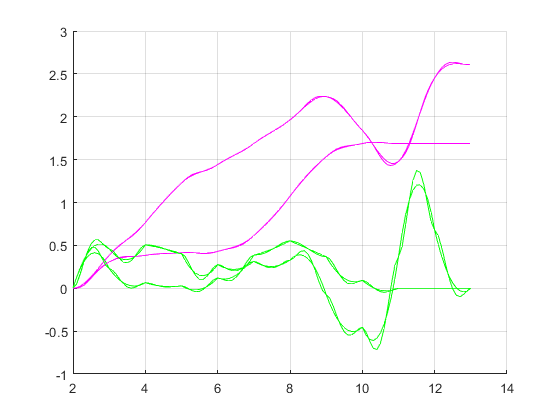

for n=2:num

b1= [P(n,1), P(n-1,1), Tg(n,1), Tg(n-1,1), 0, 0]';
b2= [P(n,2), P(n-1,2), Tg(n,2), Tg(n-1,2), 0, 0]';


p1= [  (6*b1(1) -6*b1(2)-3*b1(3)-3*b1(4)+1/2*b1(5)   -b1(6));
     (-15*b1(1)+15*b1(2)+7*b1(3)+8*b1(4)   - b1(5)+3* b1(6));...
      (10*b1(1)-10*b1(2)-4*b1(3)-6*b1(4)+1/2*b1(5)-3* b1(6));...
    b1(6);
    b1(4);
    b1(2)];



p2= [(  6*b2(1) -6*b2(2)-3*b2(3)-3*b2(4)+1/2*b2(5)   -b2(6));
     (-15*b2(1)+15*b2(2)+7*b2(3)+8*b2(4)   - b2(5)+3* b2(6));
     ( 10*b2(1)-10*b2(2)-4*b2(3)-6*b2(4)+1/2*b2(5)-3* b2(6));
     b2(6);
     b2(4);
     b2(2)];

p1d= p1(1:5).*[5; 4; 3; 2; 1];
p2d= p2(1:5).*[5; 4; 3; 2; 1];

plot(n+l,[polyval(p1,l);polyval(p2,l)]','m')
plot(n+l,[polyval(polyder(p1),l);polyval(polyder(p2),l)]','y')
plot(n+l,[polyval(p1d,l);polyval(p2d,l)]','g')
end

hold off